# Energy spectrum

Eigen-energy at different k sector: $\xi_{k,\pm } =k^2 \pm 2\sqrt{k_{\perp }^2 +B^2 }$. Here B is a real number.

First, if B=0, then $\xi_{k,\pm } =k^2 \pm 2k_{\perp }$.

The minimum of $\xi_{k,\pm }$ is located at $\frac{\partial \xi_{k,-} }{\partial k_{\perp } }=0$ with $k_z =0$


$$2k_{\perp } -2=0\to {k_{\perp } }_{\mathrm{min}} =1\to \xi_{\mathrm{min}} =-1$$


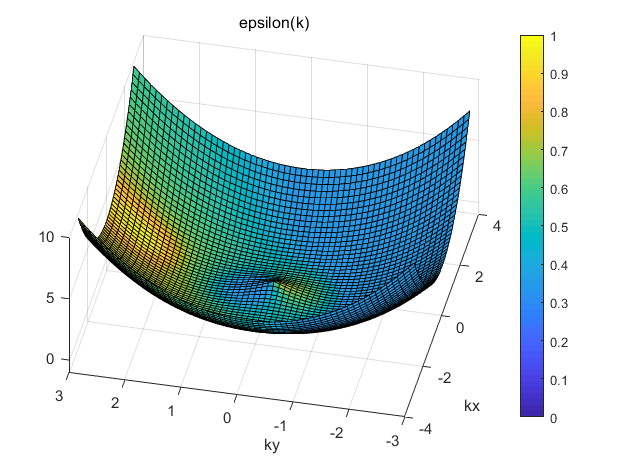

x=-3:0.1:3;
[kx,ky]=meshgrid(x,x);
Xi=kx.^2+ky.^2-2*sqrt(kx.^2+ky.^2);
surfl(kx,ky,Xi)

view([-74.72 48.61])
colorbar
title('epsilon(k)')
xlabel('kx')
ylabel('ky')

view([-77.55 57.01])

If $B\not= 0$, $\frac{\partial \xi_{k,-} }{\partial k_{\perp }^2 }=0$ leads to $1-\frac{1}{\sqrt{k_{\perp }^2 +B^2 }}=0\to k_{\perp }^2 =1-B^2 \to k_{\perp c} =\sqrt{1-B^2 }$

if $\sqrt{k_{\perp }^2 +B^2 }<1$ , this means that $\frac{\partial \xi_{k,-} }{\partial k_{\perp }^2 }<0$

therefore $\xi_{\mathrm{min}} =1-B^2 -2=-1-B^2$ with $B<B_c$, where $B_c =1$.

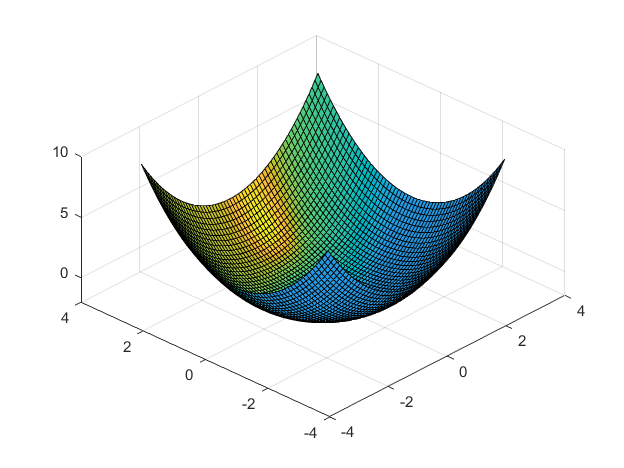

B1=1;
Xi1=kx.^2+ky.^2-2*sqrt(kx.^2+ky.^2+B1^2);
s1=surfl(kx,ky,Xi1);

s1.FaceAlpha=1;

if B is imaginary, $\xi_{k,\pm } =k^2 \pm 2\sqrt{k_{\bot }^2 +B^2 }=$$k^2 \pm 2\sqrt{k_{\bot }^2 -|{B|}^2 }$

define $k_{\perp c} =|B|$

when $k_{\perp } <k_{\perp c}$ , the real part of $\xi$ is $\mathrm{Re}\left(\xi_{k,\pm } \right)=k^2$

when $k_{\perp } >k_{\perp_c }$, $\mathrm{Re}\left(\xi_{k,\pm } \right)=\xi_{\pm }$


$$\frac{\partial \xi_{k,-} }{\partial k_{\perp }^2 }=1-\frac{1}{\sqrt{k_{\perp }^2 -{|B|}^2 }}$$
 

if $\frac{1}{\sqrt{k_{\perp }^2 -{|B|}^2 }}>1$, $\frac{\partial \xi_{k,-} }{\partial k_{\bot }^2 }$<0, $k_{\perp \mathrm{min}}^2 =1+|B|^2$, we have a local minimum $\xi_{k,-\mathrm{min}} =-1+|B|^2$

but when $k_{\perp } <k_{\perp c} \;$, $\xi_{k,-\mathrm{min}} =0$

define $|B|_c =1$

when $|B|=|B|_c$, they are both 0, so these two states have a competition.

when $|B|<|B|_c$, $\xi_{\mathrm{min}} =|B|^2 -1$.

when $|B|>|B|_c$, $\xi_{\mathrm{min}} =0$.

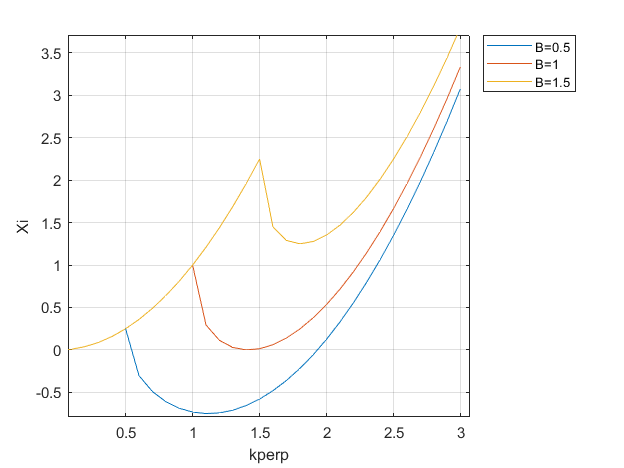

kperp=0:0.1:3;
B1=0.5;
B2=1;
B3=1.5;
Xi1=kperp.^2-2*sqrt(kperp.^2-B1^2);
Xi2=kperp.^2-2*sqrt(kperp.^2-B2^2);
Xi3=kperp.^2-2*sqrt(kperp.^2-B3^2);
Xi=kx.^2+ky.^2-2*sqrt(kx.^2+ky.^2-B2^2);
figure
plot(kperp,real(Xi1));
hold on
plot(kperp,real(Xi2))
plot(kperp,real(Xi3))

xlim([0.07 3.07])
ylim([-0.79 3.71])
grid on
legend('show')
xlabel('kperp')
ylabel('Xi')
legend({'B=0.5','B=1','B=1.5'},'Location','northeastoutside')
hold off

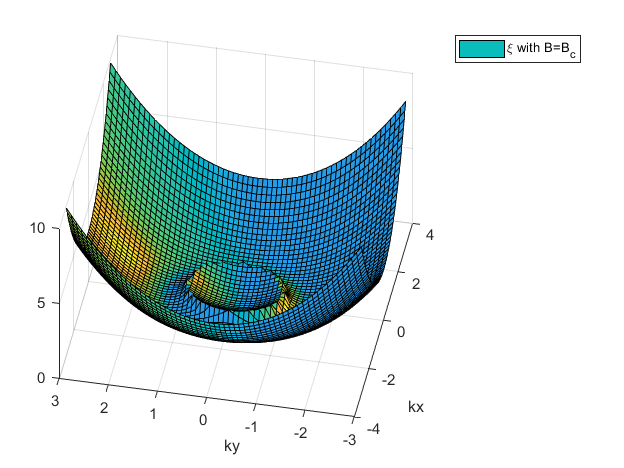

figure 
S1=surfl(kx,ky,real(Xi));

view([-73.78 49.21])
legend('\xi with B=B_c','Location','northeastoutside')
xlabel('kx')
ylabel('ky')

view([-78.70 52.81])